# Baja SAE Statistical Analysis

% loading results from .mat file
allResults = struct2cell(load('Results_Tables_Updated.mat'))

allResults = 39×1 cell array
    {100×17 table}
    { 75×15 table}
    {141×16 table}
    {120×17 table}
    {115×18 table}
    { 93×18 table}
    { 95×19 table}
    {120×18 table}
    {100×18 table}
    { 99×18 table}
    {100×17 table}
    { 89×18 table}
    {100×17 table}
    { 59×18 table}
    {115×18 table}
    { 79×18 table}


% example of imported data
allResults{1}

ans = 100×17 table
    VarName1    Event                     Overall                                 SDSM2007                VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17
    ________    _____    __________________________________________    _______________________________    ________    ________    ________    ________    ________    _________    _________    _________    ________

## Data Cleaning

% fixing results in one table
VarName17 = zeros(120, 1);
allResults{8} = [allResults{8}(:, 1:16), array2table(VarName17), allResults{8}(:, 17:18)];

### List of Events at Each Competition

% arrays for storing which events occured at which competitions
sledPull = [23 25 27 29 30 32 34 35 38 41 44 50 53 56 58];
salesPres = [22 26 28 31 36 37 40 43:60];
techEvent = [28 29 30];
techPen = [25 26 27];
techPenEnd = [22 23 24];
waterManeu = [23 27 33 35];
rockCrawl = [22 26 28 31 36 37 40 45 46 54 57]; %comes after hill climb in dataset, regular s&t comes before
mudBog = [23 29 38];

### Competition Names and Numbers

% filling row with number associated with each comp(first comp of 2000 is 1)
for i = 1:size(allResults, 1)
    allResults{i, 2} = 21 + i;
end

% array storing names of each comp
compNames = ["SDSM 2007", "UCF 2007", "RIT 2007", "Montreal 2008", "Illinois 2008", "Tennessee 2008", "Oregon 2009", "Wisconsin 2009",  "Alabama 2009", "Washington 2010", "Carolina 2010", "Rochester 2010", "Kansas 2011", "Birmingham 2011", "Illinois 2011", "Oregon 2012", "Wisconsin 2012", "Auburn 2012", "Washington 2013", "Tennessee 2013", "Rochester 2013", "UTEP 2014", "Kansas 2014","Illinois 2014", "Oregon 2015", "Auburn 2015", "Maryland 2015", "California 2016", "Tennessee 2016", "Rochester 2016", "California 2017", "Kansas 2017", "Illinois 2017", "Maryland 2018", "Kansas 2018", "Oregon 2018", "Tennessee 2019", "California 2019", "Rochester 2019"]

compNames = 1×39 string array
    "SDSM 2007"    "UCF 2007"    "RIT 2007"    "Montreal 2008"    "Illinois 2008"    "Tennessee 2008"    "Oregon 2009"    "Wisconsin 2009"    "Alabama 2009"    "Washington 2010"    "Carolina 2010"    "Rochester 2010"    "Kansas 2011"    "Birmingham 2011"    "Illinois 2011"    "Oregon 2012"    "Wisconsin 2012"    "Auburn 2012"    "Washington 2013"    "Tennessee 2013"    "Rochester 2013"    "UTEP 2014"    "Kansas 2014"    "Illinois 2014"    "Oregon 2015"    "Auburn 2015"    "Maryland 2015"    "California 2016"    "Tennessee 2016"    "Rochester 2016"    "California 2017"    "Kansas 2017"    "Illinois 2017"    "Maryland 2018"    "Kansas 2018"    "Oregon 2018"    "Tennessee 2019"    "California 2019"    "Rochester 2019"



% adding competition names to cell array
for i = 1:size(compNames, 2)
    allResults{i, 3} = compNames(i);
end

### Naming Event Columns

%for loops for naming columns. fills based on how SAE seems to fill the
%tables. competition 23 doesn't follow the pattern though
for i = 1:size(allResults, 1)
    if allResults{i, 2} ~= 23
        offset = 0;
        
        allResults{i, 1}.Properties.VariableNames([1:9]) = {'overallRank' 'carNumber' 'universityName' 'teamName' 'overallScore' 'overallDynamic' 'overallStatic' 'costScore' 'designScore'};
        
        if ismember(allResults{i, 2}, salesPres)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'salesScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, techPen)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'techPenalty'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, techEvent)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'techScore'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames([10 + offset, 11 + offset]) = {'accelScore', 'landManeuScore'};
        
        if ismember(allResults{i, 2}, mudBog)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'mudBogScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, rockCrawl)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'rockCrawlScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, sledPull)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'sledPullScore'};
        else
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'hillClimbScore'};
        end
        
        if ~ismember(allResults{i, 2}, rockCrawl)
            allResults{i, 1}.Properties.VariableNames(13 + offset) = {'susTracScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, waterManeu)
            allResults{i, 1}.Properties.VariableNames(13 + offset) = {'waterManeuScore'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames(13 + offset) = {'enduroScore'};
        
        if ismember(allResults{i, 2}, techPenEnd)
            allResults{i, 1}.Properties.VariableNames(14 + offset) = {'techPenalty'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames(14 + offset) = {'penalty'};
        
        if ~ismember(allResults{i, 2}, techPen) && ~ismember(allResults{i, 2}, techPenEnd)
            allResults{i, 1}.Properties.VariableNames(15 + offset) = {'registered'};
            allResults{i, 1}.Properties.VariableNames(16 + offset) = {'techPassed'};
        elseif ismember(allResults{i, 2}, techPen)
            allResults{i, 1}.Properties.VariableNames(15 + offset) = {'registered'};
        end
    else
        allResults{i, 1}.Properties.VariableNames = {'overallRank' 'carNumber' 'universityName' 'teamName' 'overallScore' 'designScore' 'costScore' 'accelScore' 'mudBogScore' 'susTracScore' 'waterManeuScore' 'sledPullScore' 'enduroScore' 'techPenalty' 'penalty'};
    end
    
    allResults{i, 1}.universityName = convertCharsToStrings(allResults{i, 1}.universityName);
end

allResults{1}

ans = 100×17 table
    overallRank    carNumber                  universityName                             teamName                overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    accelScore    landManeuScore    rockCrawlScore    hillClimbScore    enduroScore    techPenalty    penalty
    ___________    _________    __________________________________________    _______________________________    ____________    ______________    _____________    _________    ___________    __________    

### Cleaning University Names Data

% Paired list of names that refer to same uni

wrongNames = ["Christian Brothers College" "Arizona State Univ - Polytechnic" "California Polytechnic State Univ-SLO" "City College of the City Univ of NY";
    "Christian Brothers Univ" "Arizona State Univ Polytechnic" "California State Poly Univ-San Luis Obis" "City College of New York"];

% List of all universities that have participated in Baja SAE competitions

allUnis = getParticipatingUnis(allResults, wrongNames);

## Using the Database

% Get results from any competition
getCompResults(allResults, 28)

ans = 95×19 table
    overallRank    carNumber                universityName                         teamName            overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    techScore    accelScore    landManeuScore    rockCrawlScore    hillClimbScore    enduroScore    penalty    registered     techPassed
    ___________    _________    _______________________________________    ________________________    ____________    ______________    _____________    _________    ___________

% tells us which competition we're looking at
compNames(28)

ans = "California 2016"

% Find all comps a team attended with their results

warning('off') % function does some sketchy stuff with tables
tempResults = getCompsAttended(allResults, wrongNames, "Univ of Illinois - Urbana Champaign", allUnis)

tempResults = 30×26 table
        compName         overallRank    carNumber               universityName                     teamName         overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    techScore    accelScore    landManeuScore    rockCrawlScore    mudBogScore    hillClimbScore    sledPullScore    susTracScore    waterManeuScore    enduroScore    techPenalty    penalty    registered    techPassed    PassedTechOnTime
    _________________    ___________    _______

% write team results to table

writetable(tempResults, 'Output Tables\UIUCAllResults.xlsx')

% Grab Iron Team Award results for a given season

wrongNamesTwo = strings; % university name replacement doesn't quite work yet
getIronTeamResults(allResults, wrongNamesTwo, "2019")

ans = 20×2 cell array
    {'Univ of Michigan - Ann Arbor'       }    {'2819.09'}
    {'Ecole de Technologie Superieure'    }    {'2618.96'}
    {'Rochester Institute of Technology'  }    {'2471.58'}
    {'Cornell Univ'                       }    {'2443.57'}
    {'San Diego State Univ'               }    {'2419.61'}
    {'Univ of Akron'                      }    {'2395.99'}
    {'Univ of Maryland - Baltimore County'}    {'2337.35'}
    {'Johns Hopkins Univ'                 }    {'2009.67'}
    {'Case Western Reserve Univ'          }    {'2006.46'}
    {'Univ of Nebraska - Lincoln'         }    {'1978.42'}
    {'Univ of Nevada - Las Vegas'         }    {'1972.71'}
    {'Clarkson University'                }    {'1809.46'}
    {'Univ of Illinois - Urbana Champaign'}    {'1728.32'}
    {'Iowa State Univ'                    }    {'1714.48'}
    {'New Jersey Institute of Technology' }    {'1588.22'}
    {'Queen's Univ'                       }    {'1531.26'}
    {'Virginia Tech'              

% Ranks teams by highest average score for a given season

getAvgSeasonResults(allResults, wrongNamesTwo, "2017")

ans = 224×2 cell array
    {'West Virginia Univ'                   }    {'NaN'     }
    {'Univ of Michigan - Ann Arbor'         }    {'879.6167'}
    {'Oregon State Univ'                    }    {'823.885' }
    {'Ecole De Technologie Superieure'      }    {'803.13'  }
    {'Univ of Wisconsin - Madison'          }    {'774.05'  }
    {'Rochester Institute of Technology'    }    {'749.27'  }
    {'Northeastern Univ'                    }    {'745.615' }
    {'Cornell Univ'                         }    {'739.46'  }
    {'Univ of Akron'                        }    {'737'     }
    {'Universidad De La Salle Bajio'        }    {'731.74'  }
    {'New Jersey Institute of Technology'   }    {'714.23'  }
    {'Queen's Univ - Ontario Canada'        }    {'705.1067'}
    {'Georgia Southern Univ'                }    {'703.51'  }
    {'Brigham Young Univ'                   }    {'703.22'  }
    {'Government College of Engrg Pune'     }    {'702.73'  }
    {'California Polytechnic State Univ-SLO'}  

% Ranks teams by average results across multiple seasons, with min
% competition threshold

getAvgResults(allResults, wrongNamesTwo, ["2017" "2018" "2019"], 5)

ans = 54×3 cell array
    {'Univ of Michigan - Ann Arbor'         }    {'887.0133'}    {[9]}
    {'Ecole De Technologie Superieure'      }    {'833.2633'}    {[9]}
    {'Cornell Univ'                         }    {'830.2662'}    {[8]}
    {'Rochester Institute of Technology'    }    {'826.7789'}    {[9]}
    {'Oregon State Univ'                    }    {'816.62'  }    {[5]}
    {'Univ of Akron'                        }    {'789.7544'}    {[9]}
    {'San Diego State Univ'                 }    {'759.6189'}    {[9]}
    {'California Polytechnic State Univ-SLO'}    {'724.5717'}    {[6]}
    {'Univ of Maryland - Baltimore County'  }    {'712.6037'}    {[8]}
    {'Northeastern Univ'                    }    {'682.2757'}    {[7]}
    {'Pennsylvania College of Technology'   }    {'673.815' }    {[6]}
    {'Case Western Reserve Univ'            }    {'670.6662'}    {[8]}
    {'Univ of Nebraska - Lincoln'           }    {'666.85'  }    {[9]}
    {'Université Laval'                     }    {'653.

% Average results again, but this time recording average place

getAvgPlace(allResults, wrongNamesTwo, ["2010" "2011" "2012" "2013" "2014" "2015" "2016" "2017" "2018" "2019"], 10)

ans = 120×3 cell array
    {'Oregon State Univ'                  }    {'4.2353' }    {[17]}
    {'Cornell Univ'                       }    {'4.84'   }    {[25]}
    {'Rochester Institute of Technology'  }    {'6.2'    }    {[30]}
    {'Ecole De Technologie Superieure'    }    {'6.6333' }    {[30]}
    {'Universite Laval'                   }    {'10'     }    {[13]}
    {'Univ of Maryland - Baltimore County'}    {'16.2759'}    {[29]}
    {'San Diego State Univ'               }    {'17.7222'}    {[18]}
    {'Univ of Wisconsin - Madison'        }    {'17.8824'}    {[17]}
    {'Universidad De La Salle Bajio'      }    {'18'     }    {[10]}
    {'Northeastern Univ'                  }    {'18.1304'}    {[23]}
    {'Ohio Northern Univ'                 }    {'19.48'  }    {[25]}
    {'Univ of Nebraska - Lincoln'         }    {'20.7083'}    {[24]}
    {'Pennsylvania College of Technology' }    {'21.0714'}    {[14]}
    {'McGill Univ'                        }    {'21.2'   }    {[20]}
    {'Georg

% Find the closest competitions ever

getClosestComps(allResults)

ans = 10×4 cell array
    {["Maryland 2018"  ]}    {["Rochester Institute of Technology"]}    {[931.9100]}    {[8.2626e-04]}
    {["Carolina 2010"  ]}    {["Universite Laval"                 ]}    {[911.9000]}    {[    0.0013]}
    {["Tennessee 2013" ]}    {["Cornell Univ"                     ]}    {[845.6200]}    {[    0.0027]}
    {["Tennessee 2008" ]}    {["Queen's Univ - Ontario Canada"    ]}    {[855.7700]}    {[    0.0049]}
    {["Wisconsin 2009" ]}    {["Oregon State Univ"                ]}    {[942.9200]}    {[    0.0061]}
    {["SDSM 2007"      ]}    {[" Auburn University"               ]}    {[855.2800]}    {[    0.0083]}
    {["Illinois 2017"  ]}    {["Ecole De Technologie Superieure"  ]}    {[886.7700]}    {[    0.0112]}
    {["Kansas 2014"    ]}    {["Centro Universitario Da FEI"      ]}    {[885.6800]}    {[    0.0117]}
    {["Illinois 2014"  ]}    {["Cornell Univ"                     ]}    {[930.0300]}    {[    0.0128]}
    {["California 2017"]}    {["Ecole De Technologi

### Flexible Result Correlation

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)       8.58      8.0001    1.0725       0.28855
    x1             0.60145     0.15009    4.0073    0.00020036


Number of observations: 53, Error degrees of freedom: 51
Root Mean Squared Error: 18
R-squared: 0.239,  Adjusted R-Squared: 0.225
F-statistic vs. constant model: 16.1, p-value = 0.0002

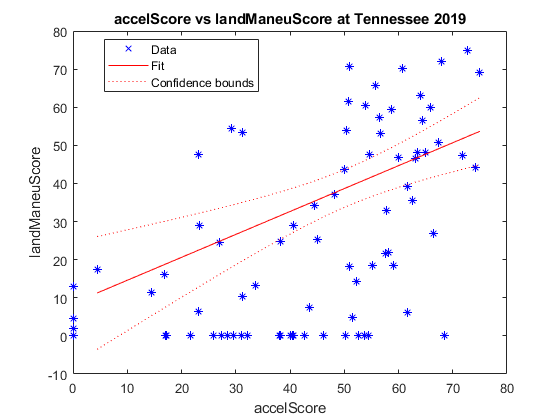

% Graphs results from any competition against eachother

linModel = graphResults2D(allResults, 58, "accelScore", "landManeuScore");

% Can easily grab the r-squared (adjusted better)
rSqr = linModel.Rsquared.Adjusted

rSqr = 0.2246

### 3D Correlation

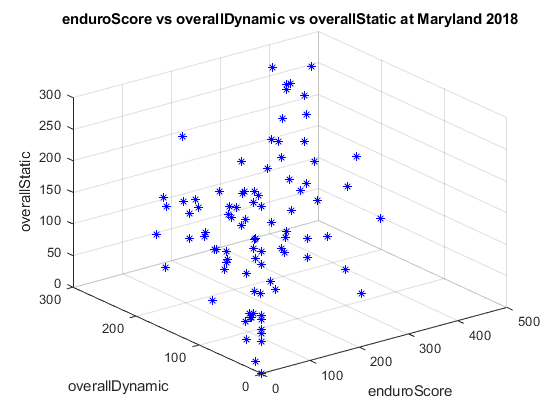


% Graph 3 sets of scores together

graphResults3D(allResults, 55, "enduroScore", "overallDynamic", "overallStatic");

## Calculating Correlation of Results

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      25.806      4.0368    6.3927    1.3622e-08
    x1             0.047075    0.008319    5.6588    2.8115e-07


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 14.2
R-squared: 0.305,  Adjusted R-Squared: 0.295
F-statistic vs. constant model: 32, p-value = 2.81e-07

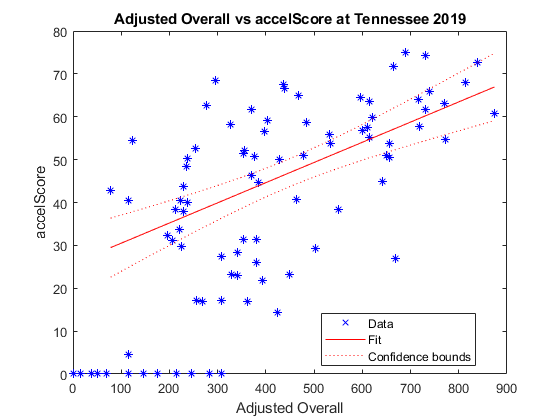

linModel2 = findResultCorrelation(allResults, 58, "accelScore");

% Once again easy to grab R-Squared
linModel2.Rsquared.Adjusted

ans = 0.2954

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      32.065       2.9163    10.995    9.7822e-18
    x1             0.050797    0.0058232    8.7231     2.803e-13


Number of observations: 83, Error degrees of freedom: 81
Root Mean Squared Error: 10
R-squared: 0.484,  Adjusted R-Squared: 0.478
F-statistic vs. constant model: 76.1, p-value = 2.8e-13

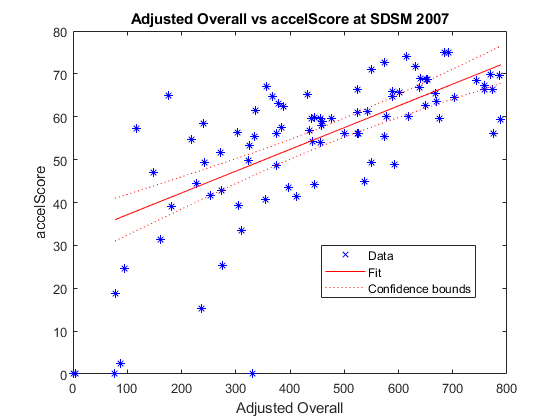

i = 22

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     39.548        3.2708    12.091    3.5488e-16
    x1             0.02095     0.0062809    3.3356     0.0016486


Number of observations: 50, Error degrees of freedom: 48
Root Mean Squared Error: 7.36
R-squared: 0.188,  Adjusted R-Squared: 0.171
F-statistic vs. constant model: 11.1, p-value = 0.00165

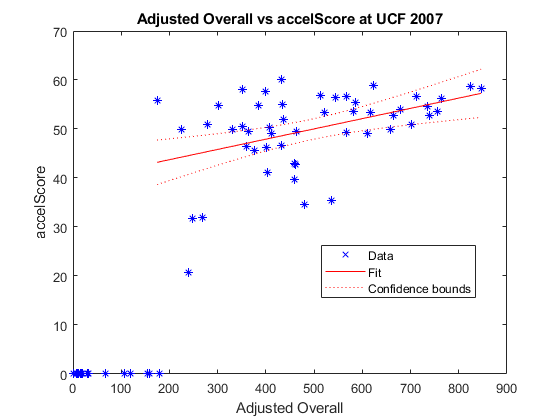

i = 23

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      35.011       2.5915     13.51     1.457e-25
    x1             0.033695    0.0045151    7.4628    1.6933e-11


Number of observations: 118, Error degrees of freedom: 116
Root Mean Squared Error: 9.93
R-squared: 0.324,  Adjusted R-Squared: 0.319
F-statistic vs. constant model: 55.7, p-value = 1.69e-11

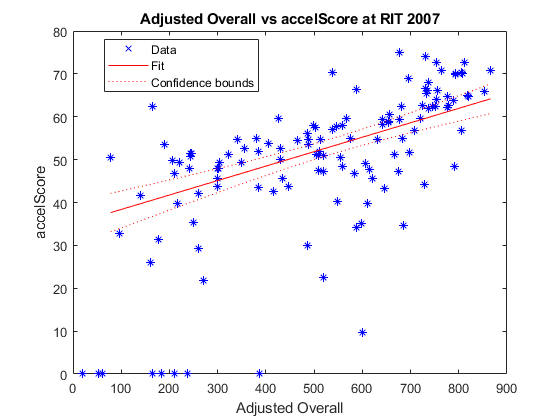

i = 24

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    _________    ______    __________

    (Intercept)       61.153       1.0707    57.114    2.4518e-71
    x1             0.0075853    0.0022889     3.314     0.0013367


Number of observations: 90, Error degrees of freedom: 88
Root Mean Squared Error: 5.49
R-squared: 0.111,  Adjusted R-Squared: 0.101
F-statistic vs. constant model: 11, p-value = 0.00134

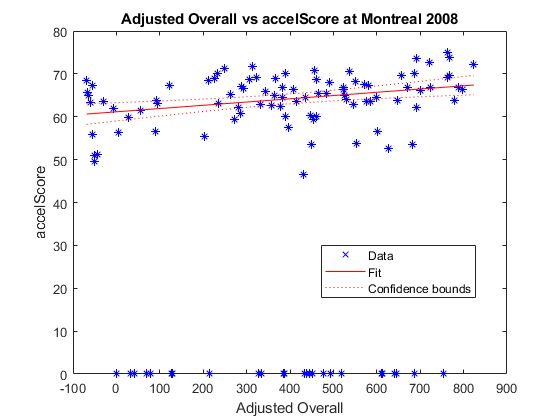

i = 25

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      52.751       2.1853    24.139    1.7674e-38
    x1             0.021036    0.0048666    4.3224    4.4046e-05


Number of observations: 82, Error degrees of freedom: 80
Root Mean Squared Error: 8.91
R-squared: 0.189,  Adjusted R-Squared: 0.179
F-statistic vs. constant model: 18.7, p-value = 4.4e-05

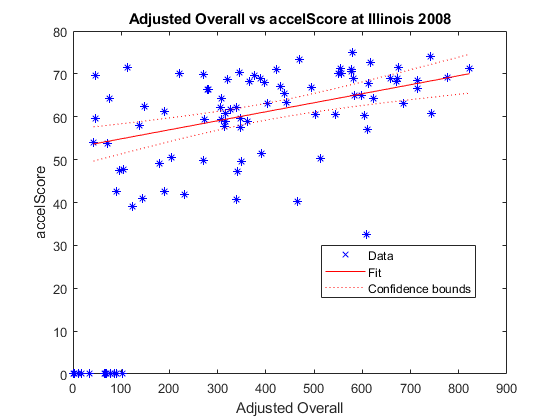

i = 26

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      28.777       3.2955    8.7322    9.0346e-12
    x1             0.023547    0.0067748    3.4756     0.0010372


Number of observations: 54, Error degrees of freedom: 52
Root Mean Squared Error: 9.33
R-squared: 0.189,  Adjusted R-Squared: 0.173
F-statistic vs. constant model: 12.1, p-value = 0.00104

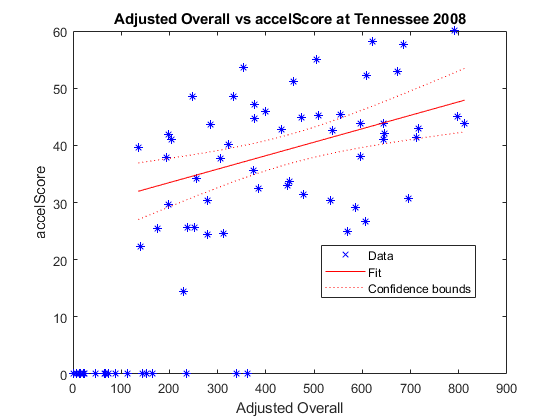

i = 27

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      47.407       3.1768    14.923    3.6182e-21
    x1             0.029099    0.0061359    4.7424     1.495e-05


Number of observations: 58, Error degrees of freedom: 56
Root Mean Squared Error: 8.46
R-squared: 0.287,  Adjusted R-Squared: 0.274
F-statistic vs. constant model: 22.5, p-value = 1.49e-05

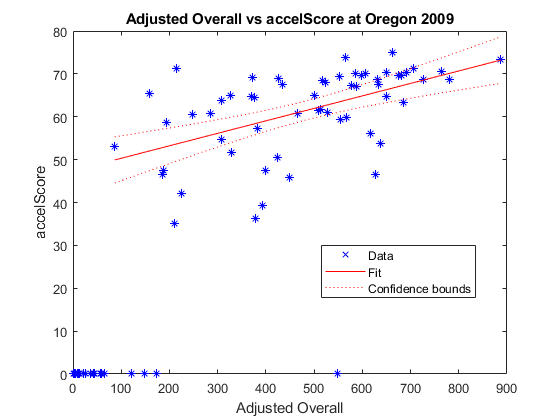

i = 28

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      45.742       1.4856    30.791    6.6052e-50
    x1             0.012335    0.0025783    4.7844    6.5914e-06


Number of observations: 93, Error degrees of freedom: 91
Root Mean Squared Error: 4.68
R-squared: 0.201,  Adjusted R-Squared: 0.192
F-statistic vs. constant model: 22.9, p-value = 6.59e-06

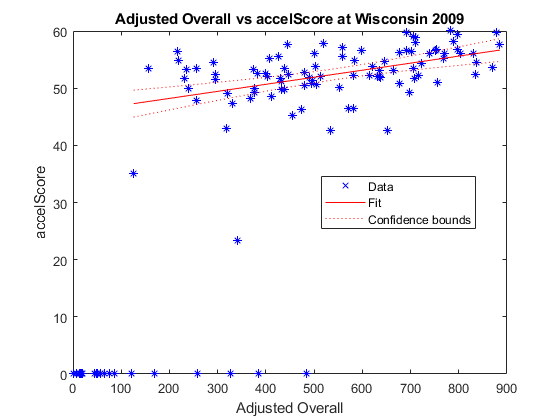

i = 29

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      57.776       1.7711    32.621    7.8481e-47
    x1             0.015977    0.0033439    4.7779    8.3048e-06


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 5.36
R-squared: 0.229,  Adjusted R-Squared: 0.219
F-statistic vs. constant model: 22.8, p-value = 8.3e-06

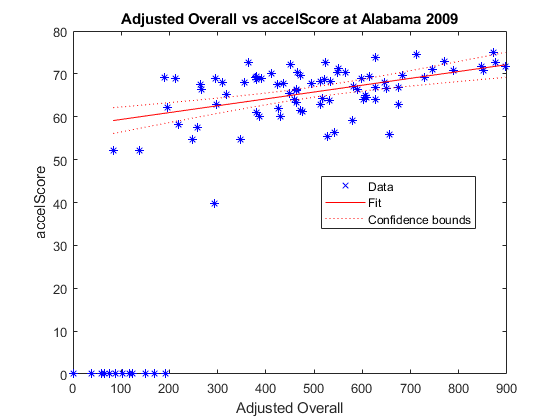

i = 30

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      45.042       3.3214    13.561    4.2337e-22
    x1             0.041738    0.0063606     6.562    5.5433e-09


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 10.4
R-squared: 0.359,  Adjusted R-Squared: 0.35
F-statistic vs. constant model: 43.1, p-value = 5.54e-09

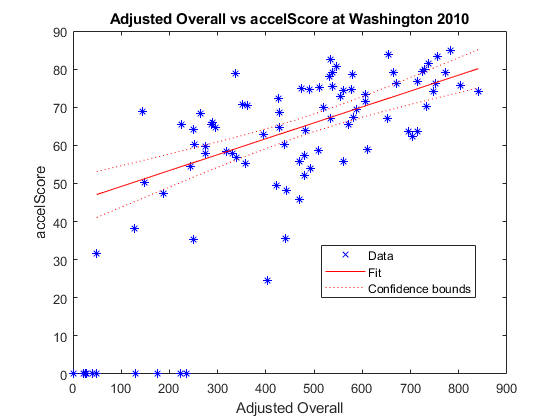

i = 31

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      36.825        4.203    8.7617    3.1303e-13
    x1             0.031244    0.0075687    4.1281     9.095e-05


Number of observations: 80, Error degrees of freedom: 78
Root Mean Squared Error: 11.1
R-squared: 0.179,  Adjusted R-Squared: 0.169
F-statistic vs. constant model: 17, p-value = 9.09e-05

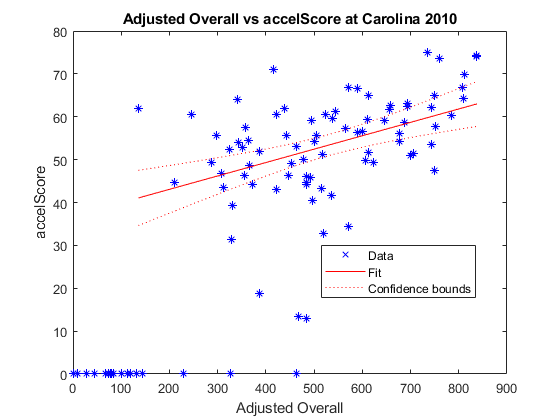

i = 32

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      40.705       1.9591    20.778    7.6308e-27
    x1             0.019183    0.0033114    5.7931    4.0779e-07


Number of observations: 54, Error degrees of freedom: 52
Root Mean Squared Error: 4.28
R-squared: 0.392,  Adjusted R-Squared: 0.381
F-statistic vs. constant model: 33.6, p-value = 4.08e-07

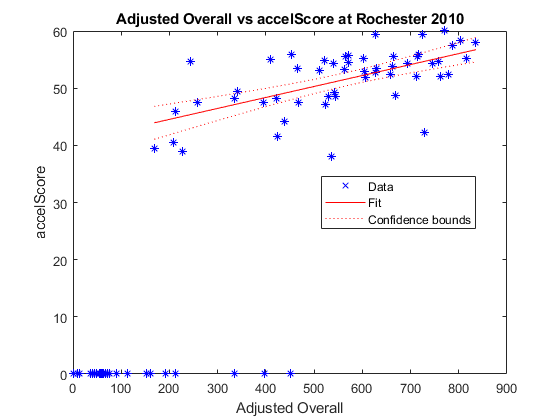

i = 33

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      41.825       2.8377    14.739    2.7079e-23
    x1             0.033059    0.0055878    5.9162    1.0595e-07


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 8.88
R-squared: 0.33,  Adjusted R-Squared: 0.321
F-statistic vs. constant model: 35, p-value = 1.06e-07

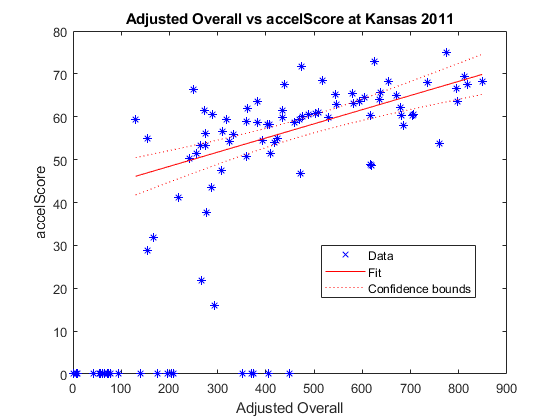

i = 34

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      18.643       4.3804     4.256    0.00013119
    x1             0.037127    0.0085934    4.3205    0.00010793


Number of observations: 40, Error degrees of freedom: 38
Root Mean Squared Error: 11.5
R-squared: 0.329,  Adjusted R-Squared: 0.312
F-statistic vs. constant model: 18.7, p-value = 0.000108

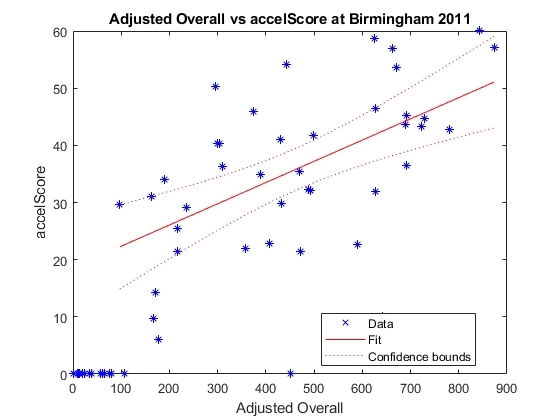

i = 35

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      37.907       3.0318    12.503    3.1973e-20
    x1             0.034033    0.0060053    5.6672    2.4078e-07


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 9.67
R-squared: 0.294,  Adjusted R-Squared: 0.285
F-statistic vs. constant model: 32.1, p-value = 2.41e-07

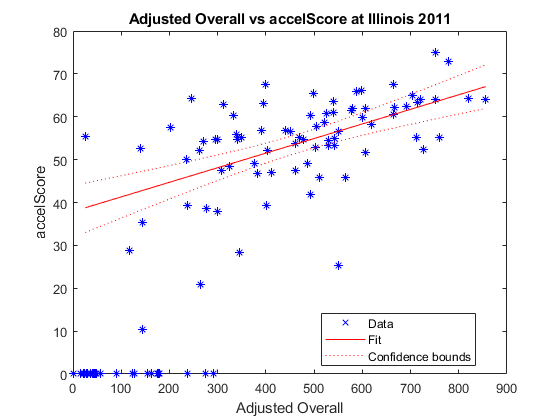

i = 36

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      29.251       3.7509    7.7984    5.1017e-10
    x1             0.043995    0.0072201    6.0933     1.944e-07


Number of observations: 49, Error degrees of freedom: 47
Root Mean Squared Error: 9.78
R-squared: 0.441,  Adjusted R-Squared: 0.429
F-statistic vs. constant model: 37.1, p-value = 1.94e-07

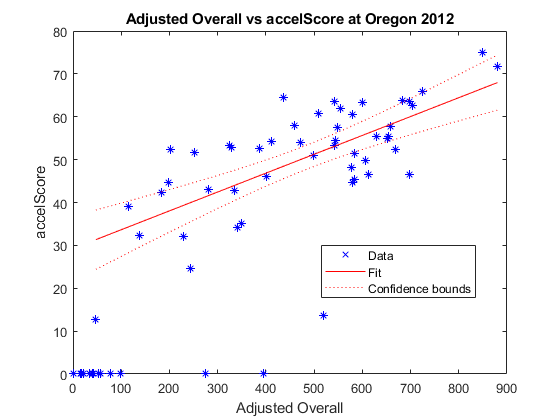

i = 37

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      20.461       3.3091    6.1832    1.9799e-08
    x1             0.034901    0.0059758    5.8404    8.8144e-08


Number of observations: 89, Error degrees of freedom: 87
Root Mean Squared Error: 9.33
R-squared: 0.282,  Adjusted R-Squared: 0.273
F-statistic vs. constant model: 34.1, p-value = 8.81e-08

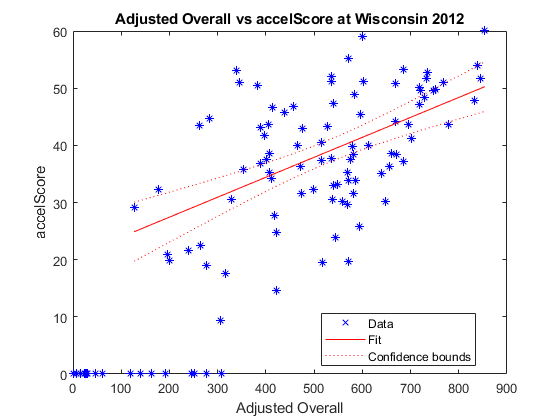

i = 38

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      43.508       3.3383    13.033    3.6707e-20
    x1             0.027757    0.0065788    4.2191    7.4301e-05


Number of observations: 70, Error degrees of freedom: 68
Root Mean Squared Error: 10.7
R-squared: 0.207,  Adjusted R-Squared: 0.196
F-statistic vs. constant model: 17.8, p-value = 7.43e-05

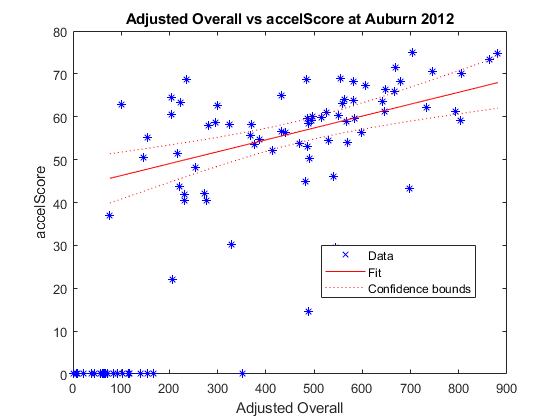

i = 39

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)       33.21       3.9922    8.3187    1.7941e-11
    x1             0.038441    0.0079995    4.8055    1.1309e-05


Number of observations: 60, Error degrees of freedom: 58
Root Mean Squared Error: 10.8
R-squared: 0.285,  Adjusted R-Squared: 0.272
F-statistic vs. constant model: 23.1, p-value = 1.13e-05

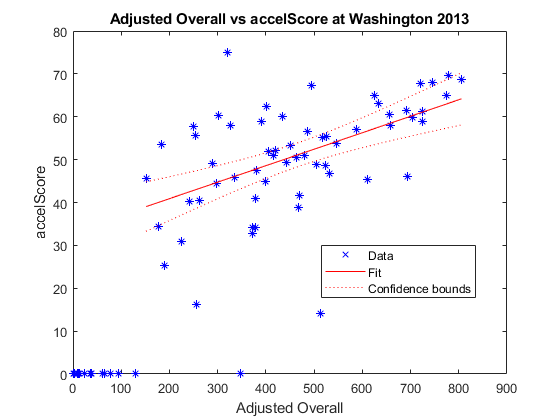

i = 40

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      41.935       2.9619    14.158    1.6974e-22
    x1             0.033015    0.0060825    5.4278    7.3127e-07


Number of observations: 74, Error degrees of freedom: 72
Root Mean Squared Error: 10.1
R-squared: 0.29,  Adjusted R-Squared: 0.281
F-statistic vs. constant model: 29.5, p-value = 7.31e-07

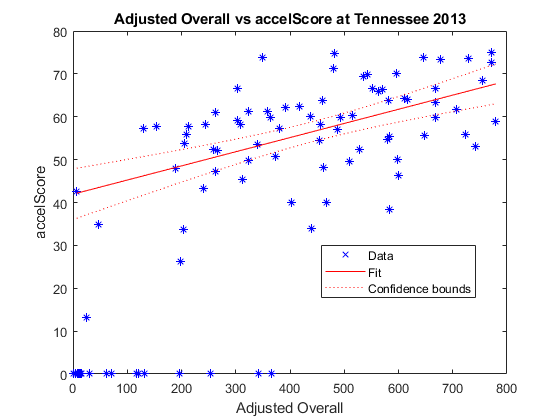

i = 41

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      37.901         2.57    14.748    7.2541e-24
    x1             0.040837    0.0049071    8.3221    2.9077e-12


Number of observations: 77, Error degrees of freedom: 75
Root Mean Squared Error: 8.36
R-squared: 0.48,  Adjusted R-Squared: 0.473
F-statistic vs. constant model: 69.3, p-value = 2.91e-12

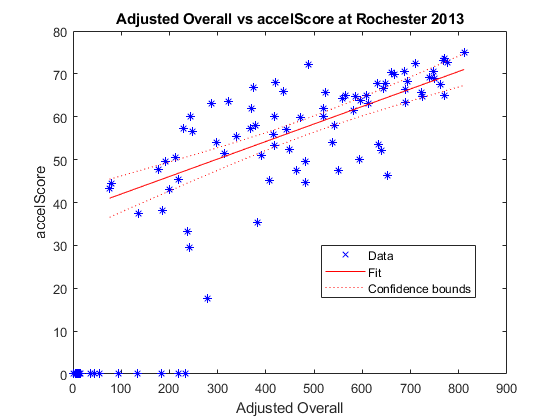

i = 42

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      55.632       1.1486    48.435    3.9343e-56
    x1             0.017751    0.0024394    7.2769     3.637e-10


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 4.38
R-squared: 0.427,  Adjusted R-Squared: 0.419
F-statistic vs. constant model: 53, p-value = 3.64e-10

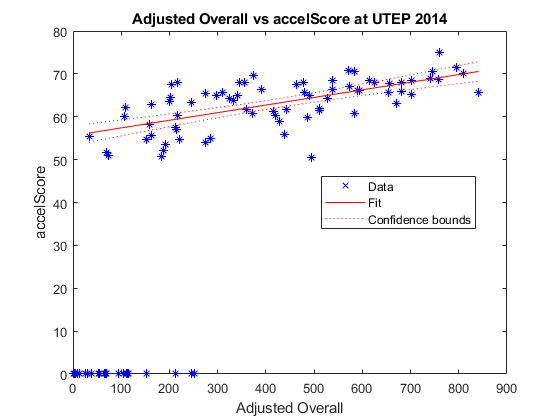

i = 43

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      33.719       3.0186    11.171    3.2327e-18
    x1             0.039253    0.0066249     5.925    6.8501e-08


Number of observations: 85, Error degrees of freedom: 83
Root Mean Squared Error: 11.9
R-squared: 0.297,  Adjusted R-Squared: 0.289
F-statistic vs. constant model: 35.1, p-value = 6.85e-08

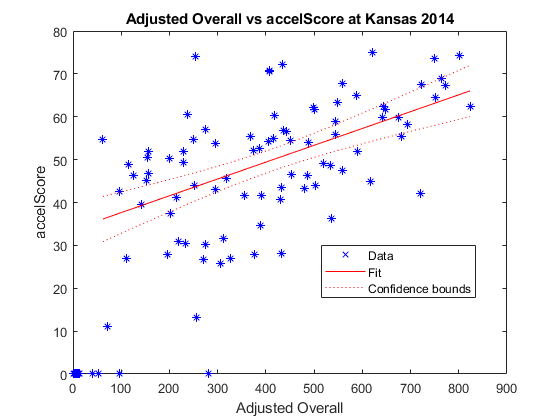

i = 44

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      37.924       2.3219    16.333      1.67e-27
    x1             0.039703    0.0051053    7.7768    1.9308e-11


Number of observations: 84, Error degrees of freedom: 82
Root Mean Squared Error: 8.79
R-squared: 0.424,  Adjusted R-Squared: 0.417
F-statistic vs. constant model: 60.5, p-value = 1.93e-11

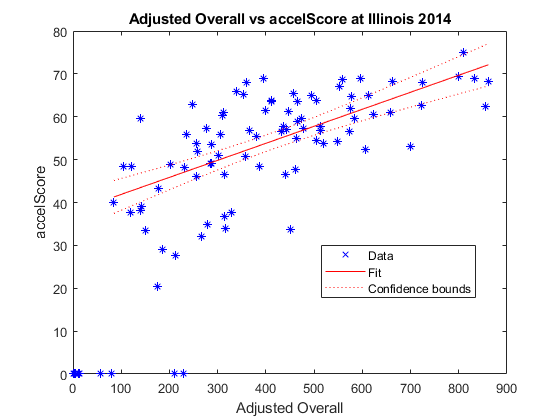

i = 45

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      23.598      3.0074    7.8465    2.7344e-11
    x1             0.051022    0.006027    8.4656     1.877e-12


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 10.6
R-squared: 0.495,  Adjusted R-Squared: 0.488
F-statistic vs. constant model: 71.7, p-value = 1.88e-12

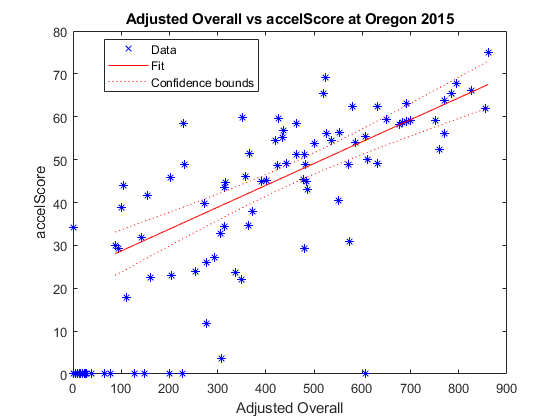

i = 46

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      21.227       4.5463     4.669    1.3207e-05
    x1             0.047296    0.0086944    5.4399    6.5936e-07


Number of observations: 76, Error degrees of freedom: 74
Root Mean Squared Error: 13.4
R-squared: 0.286,  Adjusted R-Squared: 0.276
F-statistic vs. constant model: 29.6, p-value = 6.59e-07

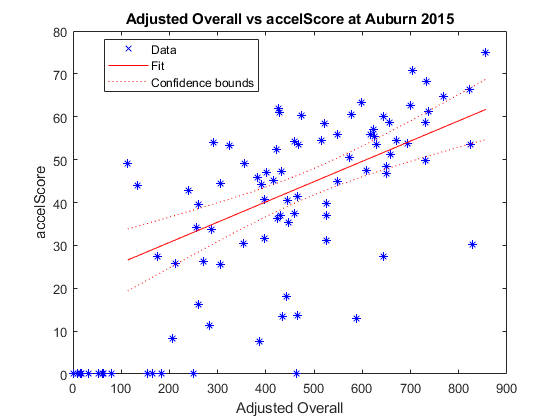

i = 47

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      24.208      3.8222    6.3336     1.601e-08
    x1             0.044973    0.006913    6.5055    7.7276e-09


Number of observations: 77, Error degrees of freedom: 75
Root Mean Squared Error: 11.5
R-squared: 0.361,  Adjusted R-Squared: 0.352
F-statistic vs. constant model: 42.3, p-value = 7.73e-09

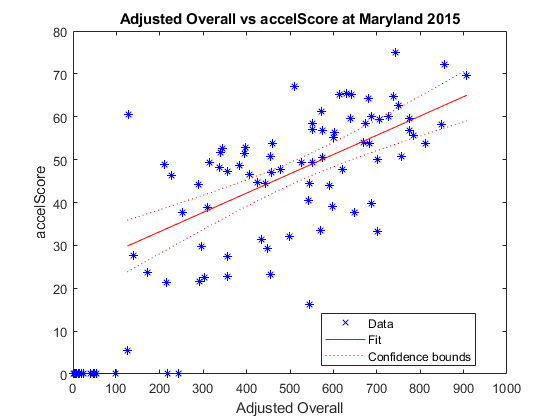

i = 48

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      27.261       3.4994    7.7903    2.5753e-11
    x1             0.041338    0.0065974    6.2658    1.9662e-08


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 11.1
R-squared: 0.338,  Adjusted R-Squared: 0.329
F-statistic vs. constant model: 39.3, p-value = 1.97e-08

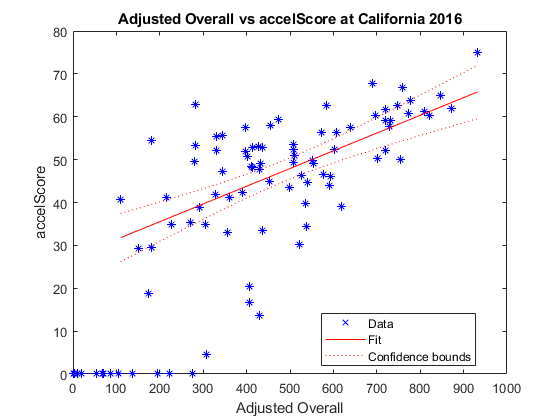

i = 49

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      30.996       3.8474    8.0563     1.315e-11
    x1             0.030474    0.0077818    3.9161    0.00020451


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 12.3
R-squared: 0.178,  Adjusted R-Squared: 0.166
F-statistic vs. constant model: 15.3, p-value = 0.000205

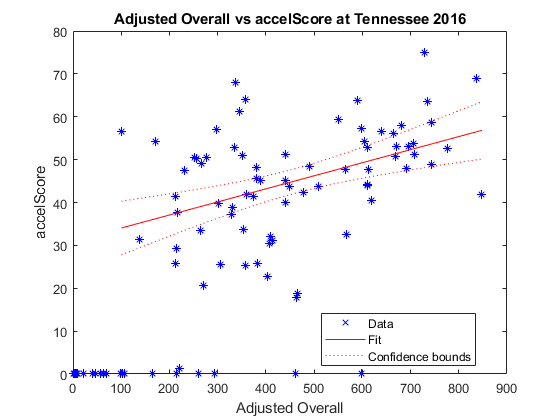

i = 50

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      23.331       3.6228    6.4399    6.8215e-09
    x1             0.047098    0.0068301    6.8956    8.8968e-10


Number of observations: 87, Error degrees of freedom: 85
Root Mean Squared Error: 11.9
R-squared: 0.359,  Adjusted R-Squared: 0.351
F-statistic vs. constant model: 47.5, p-value = 8.9e-10

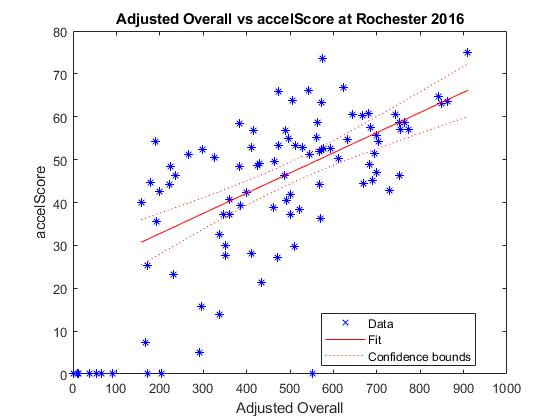

i = 51

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     19.041       3.9548    4.8146    8.5796e-06
    x1             0.04425     0.007975    5.5486    5.1292e-07


Number of observations: 70, Error degrees of freedom: 68
Root Mean Squared Error: 11.9
R-squared: 0.312,  Adjusted R-Squared: 0.302
F-statistic vs. constant model: 30.8, p-value = 5.13e-07

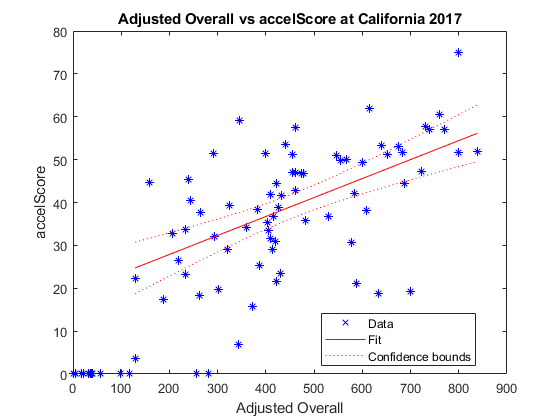

i = 52

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     22.231       5.6299    3.9488    0.00023318
    x1             0.03811     0.011438     3.332     0.0015767


Number of observations: 55, Error degrees of freedom: 53
Root Mean Squared Error: 13
R-squared: 0.173,  Adjusted R-Squared: 0.158
F-statistic vs. constant model: 11.1, p-value = 0.00158

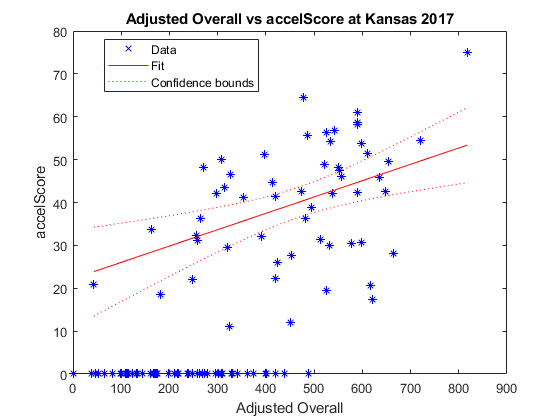

i = 53

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      25.379       3.5588    7.1314    3.3842e-10
    x1             0.048278    0.0073092    6.6051    3.5496e-09


Number of observations: 85, Error degrees of freedom: 83
Root Mean Squared Error: 13.1
R-squared: 0.345,  Adjusted R-Squared: 0.337
F-statistic vs. constant model: 43.6, p-value = 3.55e-09

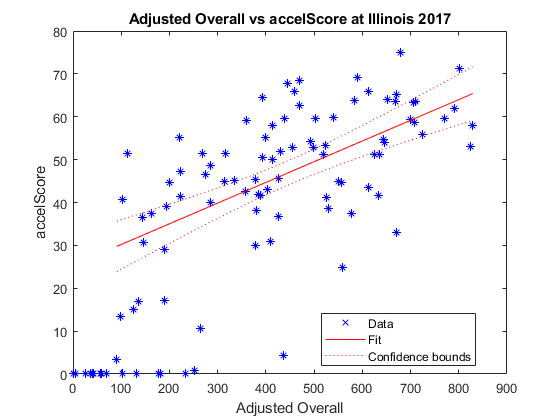

i = 54

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      13.076       3.5259    3.7085    0.00039722
    x1             0.062194    0.0072945    8.5261    1.1882e-12


Number of observations: 77, Error degrees of freedom: 75
Root Mean Squared Error: 12.2
R-squared: 0.492,  Adjusted R-Squared: 0.485
F-statistic vs. constant model: 72.7, p-value = 1.19e-12

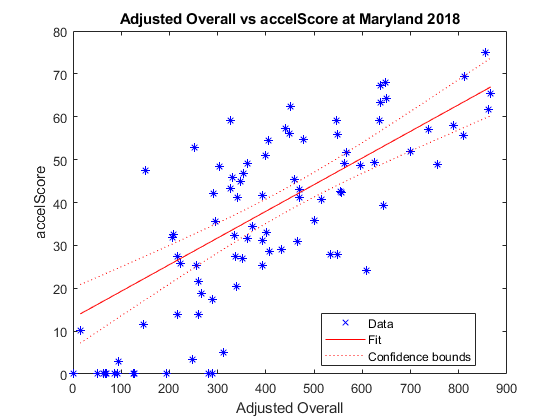

i = 55

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)      7.6842      5.1751    1.4848      0.14208
    x1             0.066724    0.010249    6.5105    9.629e-09


Number of observations: 72, Error degrees of freedom: 70
Root Mean Squared Error: 12.7
R-squared: 0.377,  Adjusted R-Squared: 0.368
F-statistic vs. constant model: 42.4, p-value = 9.63e-09

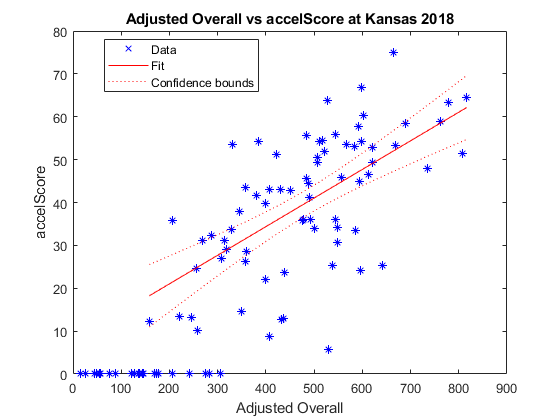

i = 56

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      10.348       3.1021    3.3358     0.0013045
    x1             0.069112    0.0062204    11.111    9.7072e-18


Number of observations: 80, Error degrees of freedom: 78
Root Mean Squared Error: 10.3
R-squared: 0.613,  Adjusted R-Squared: 0.608
F-statistic vs. constant model: 123, p-value = 9.71e-18

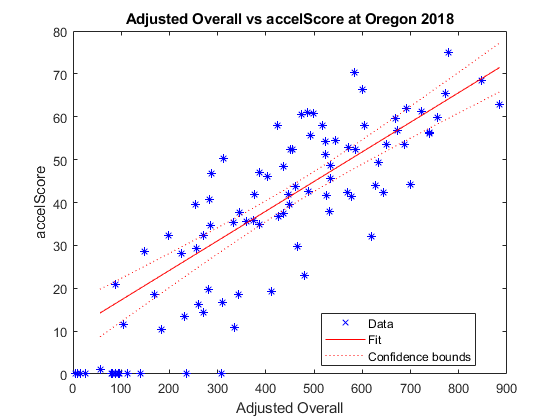

i = 57

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      25.806      4.0368    6.3927    1.3622e-08
    x1             0.047075    0.008319    5.6588    2.8115e-07


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 14.2
R-squared: 0.305,  Adjusted R-Squared: 0.295
F-statistic vs. constant model: 32, p-value = 2.81e-07

i = 58

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      24.433       3.1161    7.8409    2.0586e-11
    x1             0.053179    0.0059828    8.8886    1.9663e-13


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 9.09
R-squared: 0.506,  Adjusted R-Squared: 0.5
F-statistic vs. constant model: 79, p-value = 1.97e-13

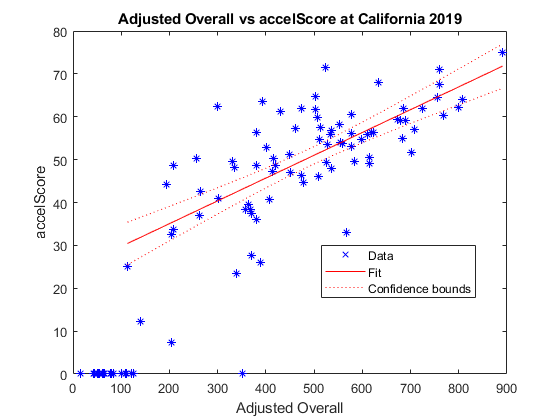

i = 59

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      29.149       3.7772    7.7171    3.0947e-11
    x1             0.050163    0.0073483    6.8265     1.601e-09


Number of observations: 81, Error degrees of freedom: 79
Root Mean Squared Error: 11.7
R-squared: 0.371,  Adjusted R-Squared: 0.363
F-statistic vs. constant model: 46.6, p-value = 1.6e-09

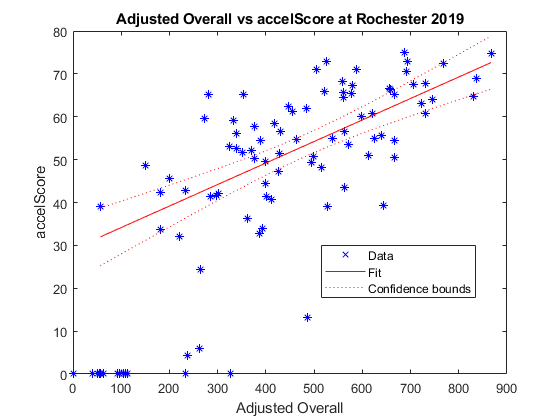

i = 60

rSqrs =     0.4780
    0.1713
    0.3186
    0.1008
    0.1792
    0.1729
    0.2738
    0.1922
    0.2187
    0.3503


rSqrs =     0.4780
    0.1713
    0.3186
    0.1008
    0.1792
    0.1729
    0.2738
    0.1922
    0.2187
    0.3503


rSqrs = getCorrelationData('accelScore', allResults)

mean(rSqrs(~isnan(rSqrs)))

ans = 0.3167

std(rSqrs(~isnan(rSqrs)))

ans = 0.1149

figure
pd = fitdist(rSqrs(~isnan(rSqrs)), 'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.316709   [0.279477, 0.353942]
    sigma = 0.114857   [0.0938667, 0.148026]


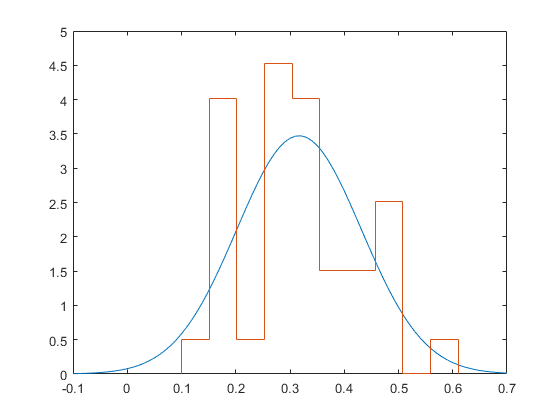

x = -0.1:0.01:0.7;
y = pdf(pd, x);
plot(x, y)
hold on
histogram(rSqrs, 10, 'DisplayStyle', 'stairs', 'Normalization','pdf')